# Simulation Of Ground Acceleration Record

Time series of acceleration records are simulated using a stationary process that is "weighted" by an envelope function. The function that fulfils this procedure is 'seismSim'. The parameters of the simulated seismic record are retrieved using the function 'fitKT'

## Ground acceleration record computation

%frequency vector
f = linspace(0,48,4096);

- select `bandwidth of the earthquake excitation`

zeta = 0.3;

- select the standard deviation of `earthquake excitation`

sigma = 0.35;

- select `dominant frequency of the earthquake excitation (Hz).`

fn = 10;

- select `value of the envelop function at 90 percent of the duration.`

T90 = 0.25;

- select `normalized duration time when ground motion achieves peak.`

eps = 0.4;

- **select **duration of ground motion;

tn = 60;

Calling this function

% function call
[y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn); 
% y: acceleration record
% t: time

### Plot Function

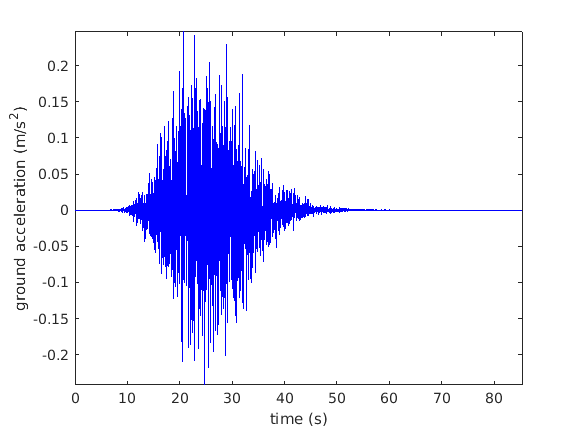

plot(t,y,'b');
xlabel('time (s)')
ylabel('ground acceleration (m/s^2)')
axis tight

Earthquake data has been generated.

### Wavelet Transform:

ler's first plot using default parameters

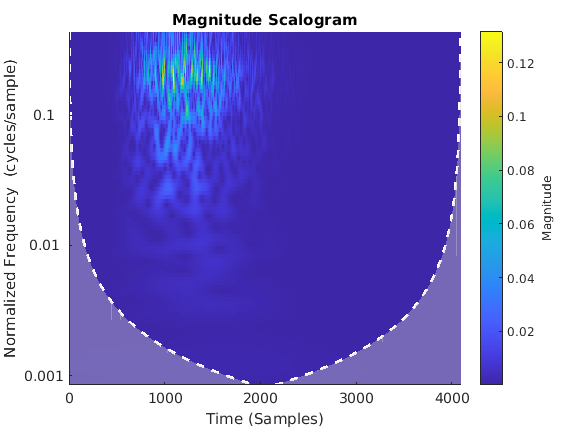

cwt(y)

specify the parameters

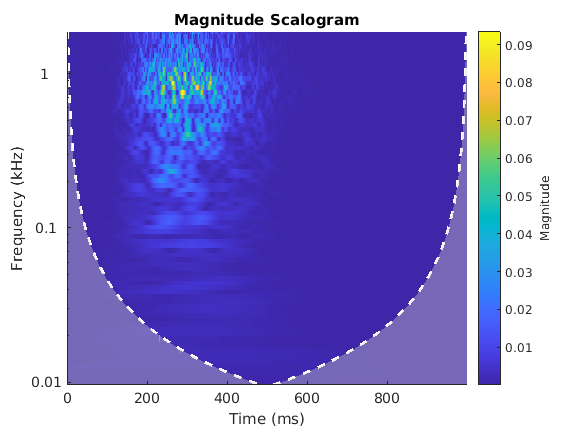

cwt(y,'bump',4096)

Create a CWT filter bank that can be applied to the signal. Since the signal component frequencies are known, set the frequency limits of the filter bank to a narrow range that includes the known frequencies. To confirm the range, plot the magnitude frequency responses for the filter bank

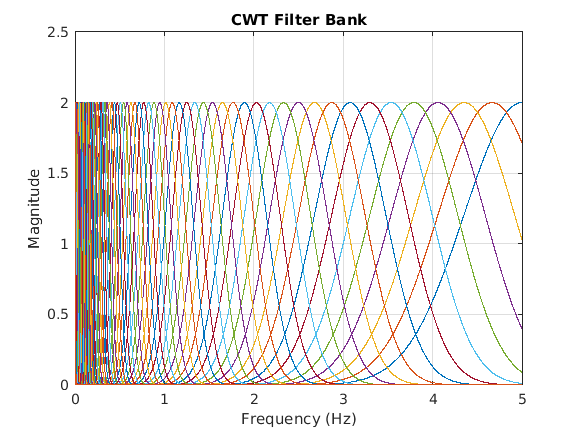

fb = cwtfilterbank('SignalLength',numel(y),'SamplingFrequency',fn,...
    'FrequencyLimits',[0 5]);
figure
freqz(fb)

figure
cwt(y,'FilterBank',fb)

The plot uses a logarithmic frequency axis because frequencies in the CWT are logarithmic. In MATLAB, logarithmic axes are in powers of 10 (decades). You can use [`cwtfreqbounds`](https://in.mathworks.com/help/wavelet/ref/cwtfreqbounds.html) to determine what the minimum and maximum wavelet bandpass frequencies are for a given signal length, sampling frequency, and wavelet.

[minf,maxf] = cwtfreqbounds(numel(y),1000);

You see that by default MATLAB has placed frequency ticks at 10 and 100 because those are the powers of 10 between the minimum and maximum frequencies. If you wish to add more frequency axis ticks, you can obtain a logarithmically spaced set of frequencies between the minimum and maximum frequencies using the following.

numfreq = 10;
freq = logspace(log10(minf),log10(maxf),numfreq);

Next, get the handle to the current axes and replace the frequency axis ticks and labels with the following.

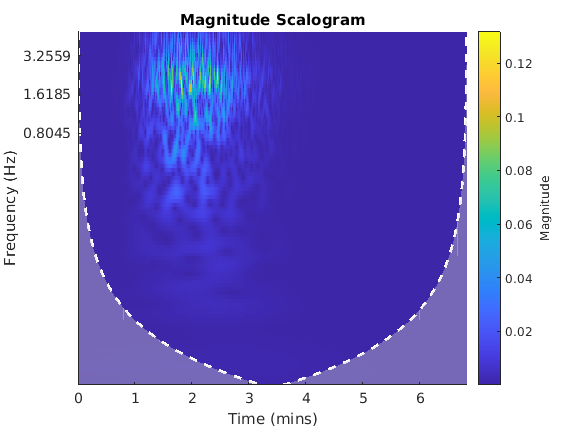

AX = gca;
AX.YTickLabelMode = 'auto';
AX.YTick = freq;

In the CWT, frequencies are computed in powers of two. To create the frequency ticks and tick labels in powers of two, you can do the following.

`newplot;`

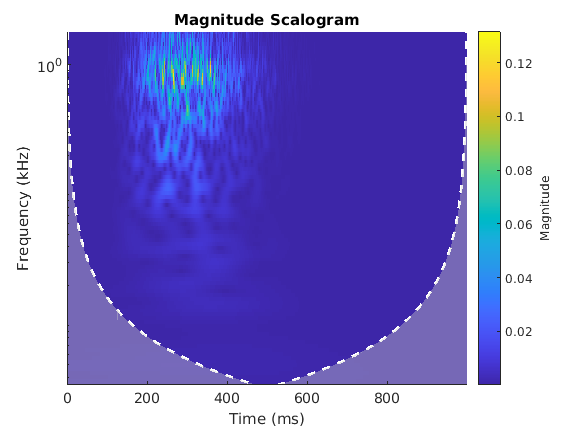

cwt(y,4096);
AX = gca;
freq = 2.^(round(log2(minf)):round(log2(maxf)));
AX.YTickLabelMode = 'auto';
AX.YTick = freq;

color change

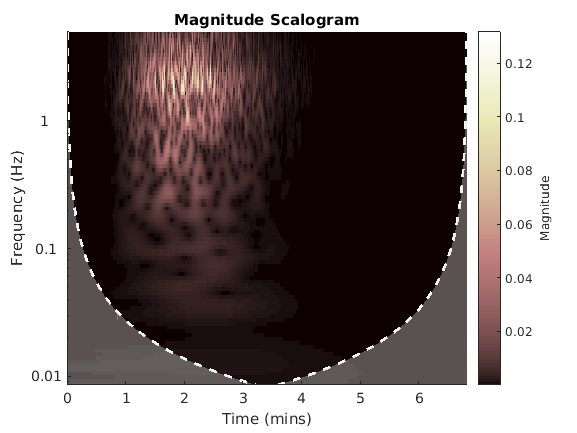

figure;
cwt(y,'FilterBank',fb)
colormap(pink(240))

**Plot CWT Scalogram in Subplot**

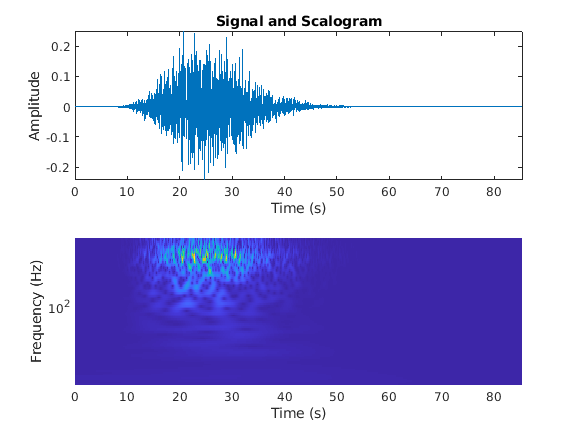

[cfs,frq] = cwt(y,4096);
tms = (0:numel(y)-1)/4096;
figure
subplot(2,1,1)
plot(t,y)
axis tight
title('Signal and Scalogram')
xlabel('Time (s)')
ylabel('Amplitude')
subplot(2,1,2)
surface(t,frq,abs(cfs))
axis tight
shading flat
xlabel('Time (s)')
ylabel('Frequency (Hz)')
set(gca,'yscale','log')

**Time-Frequency Analysis: Fourier Transform**

The Fourier transform (FT) is very good at identifying frequency components present in a signal. However, the FT does not identify when the frequency components occur.

Plot the magnitude spectrum of the signal. Zoom in on the region between 0 and 200 Hz.

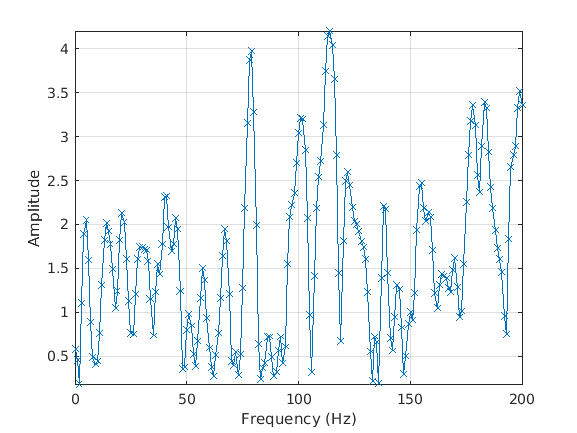

sigLen = numel(y);
fchirp = fft(y);
Fs=4096;
fr = Fs*(0:1/Fs:1-1/Fs);
plot(fr(1:sigLen/2),abs(fchirp(1:sigLen/2)),'x-')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
axis tight
grid on
xlim([0 200])

**Time-Frequency Analysis: Short-Time Fourier Transform**

The Fourier transform does not provide time information. To determine when the changes in frequency occur, the short-time Fourier transform (STFT) approach segments the signal into different chunks and performs the FT on each chunk. The STFT tiling in the time-frequency plane is shown here.

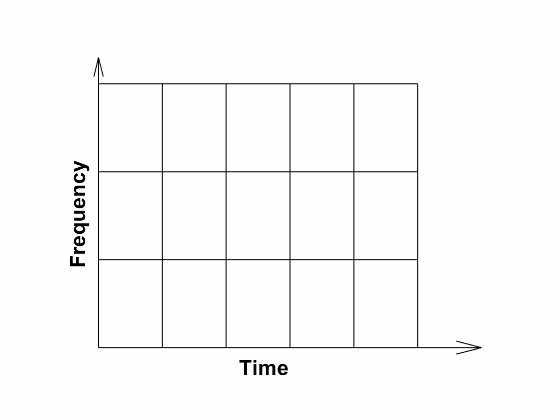

The STFT provides some information on both the timing and the frequencies at which a signal event occurs. However, choosing a window (segment) size is key. For time-frequency analysis using the STFT, choosing a shorter window size helps obtain good time resolution at the expense of frequency resolution. Conversely, choosing a larger window helps obtain good frequency resolution at the expense of time resolution.

Once you pick a window size, it remains fixed for the entire analysis. If you can estimate the frequency components you are expecting in your signal, then you can use that information to pick a window size for the analysis.

In 3D view we can see how the scalogram will look like

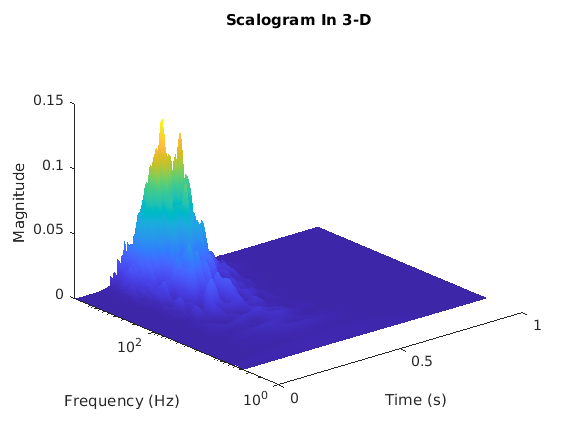

helperPlotScalogram3d(y,Fs)

Use the helper function `helperPlotScalogram` to plot the scalogram of the signal and the instantaneous frequencies. The source code for `helperPlotScalogram` is listed in the appendix. The instantaneous frequencies align well with the scalogram features.

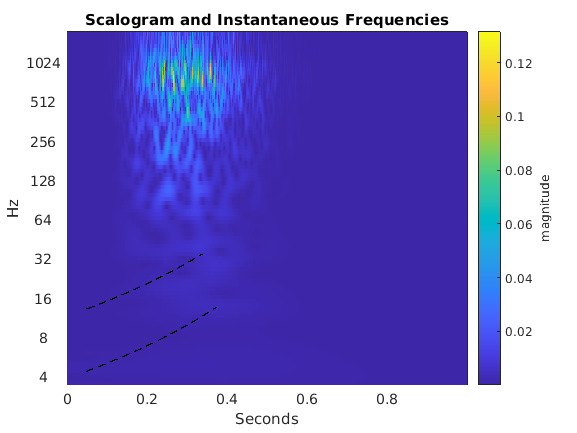

helperPlotScalogram(y,Fs)

# Frequency- and Time-Localized Reconstruction from the Continuous Wavelet Transform

[wt,f] = cwt(y,1);

Reconstruct the earthquake data, adding the signal mean back into the transformed data.

xrec = icwt(wt,f,[0.030 0.070],'SignalMean',mean(y));

Plot and compare the original data and the data for frequencies in the range of [0.030, 0.070] Hz.

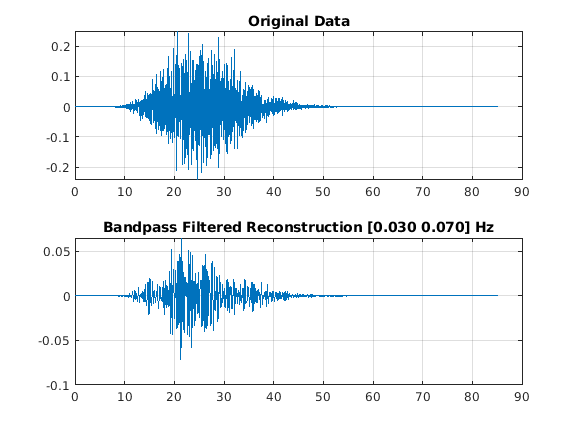

subplot(2,1,1)
plot(t,y)
grid on
title('Original Data')
subplot(2,1,2)
plot(t,xrec)
grid on
title('Bandpass Filtered Reconstruction [0.030 0.070] Hz')

Index in position 1 exceeds array bounds (must not exceed 1).

Error in cwtft2 (line 172)
dxxdyy  = abs( (xx(1,2) - xx(1,1)) * (yy(2,1) - yy(1,1)));

#### Simulation Function:

function [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn)
% [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn) generate one time series
% corresponding to acceleration record from a seismometer. The function
% requires 7 inputs, and gives 2 outputs. The time series is generated in
% two steps: First a stationnary process is created based on the Kanai-
% Tajimi spectrum, then an envelope function is used to transform this 
% stationnary time series into a non-stationary record. For more
% information, see [1-3].
% [1] Lin, Y. K., & Yong, Y. (1987). Evolutionary Kanai-Tajimi earthquake
% models. Journal of engineering mechanics, 113(8), 1119-1137.
% [2] Rofooei, F. R., Mobarake, A., & Ahmadi, G. (2001). 
% Generation of artificial earthquake records with a nonstationary 
% KanaiTajimi model. Engineering Structures, 23(7), 827-837.
% [3] Guo, Y., & Kareem, A. (2016). 
% System identification through nonstationary data using TimeFrequency Blind
% Source Separation. Journal of Sound and Vibration, 371, 110-131.
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% INPUTS 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% sigma: [1 x 1 ]: standard deviation of the excitation.
% fn: [1 x 1 ]: dominant frequency of the earthquake excitation (Hz).
% zeta: [1 x 1 ]:  bandwidth of the earthquake excitation.
% f: [ 1 x M ]: frequency vector for the Kanai-tajimi spectrum.
% T90: [1 x 1 ]: value at 90 percent of the duration.
% eps: [1 x 1 ]: normalized duration time when ground motion achieves peak.
% tn: [1 x 1 ]: duration of ground motion.
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% OUTPUTS 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% y: size: [ 1 x N ] : Simulated aceleration record
% t: size: [ 1 x N ] : time
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% EXAMPLE:
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% f = linspace(0,40,2048);
% zeta = 0.3;
% sigma = 0.9;
% fn =5;
% T90 = 0.3;
% eps = 0.4;
% tn = 30;
% [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn);
% figure
% plot(t,y);axis tight
% xlabel('time(s)');
% ylabel('ground acceleration (m/s^2)')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% see also fitKT.m
% Author: Etienne Cheynet - modified: 23/04/2016

%% Initialisation
w = 2*pi.*f;
fs = f(end); dt = 1/fs;
f0= median(diff(f));
Nfreq = numel(f);
t = 0:dt:dt*(Nfreq-1);

%% Generation of the spectrum S
fn = fn *2*pi; % transformation in rad;
s0 = 2*zeta*sigma.^2./(pi.*fn.*(4*zeta.^2+1));
A = fn.^4+(2*zeta*fn*w).^2;
B = (fn.^2-w.^2).^2+(2*zeta*fn.*w).^2;
S = s0.*A./B; % single sided PSD


%% Time series generation - Monte Carlo simulation
A = sqrt(2.*S.*f0);
B =cos(w'*t + 2*pi.*repmat(rand(Nfreq,1),[1,Nfreq]));
x = A*B; % stationary process

%% Envelop function E
b = -eps.*log(T90)./(1+eps.*(log(T90)-1));
c = b./eps;
a = (exp(1)./eps).^b;
E = a.*(t./tn).^b.*exp(-c.*t./tn);

%% Envelop multiplied with stationary process to get y
y = x.*E;

end

**helperPlotSpectrogram**

function helperPlotSpectrogram(sig,t,Fs,timeres)
% This function is only intended to support this wavelet example.
% It may change or be removed in a future release.

[px,fx,tx] = pspectrum(sig,Fs,'spectrogram','TimeResolution',timeres/1000);
hp = pcolor(tx,fx,20*log10(abs(px)));
hp.EdgeAlpha = 0;
ylims = hp.Parent.YLim;
yticks = hp.Parent.YTick;
cl = colorbar;
cl.Label.String = 'Power (dB)';
axis tight
hold on
title(['Time Resolution: ',num2str(timeres),' ms'])
xlabel('Time (s)')
ylabel('Hz');
dt  = 1/Fs;
idxbegin = round(0.1/dt);
idxend1 = round(0.68/dt);
idxend2 = round(0.75/dt);
instfreq1 = abs((15*pi)./(0.8-t).^2)./(2*pi);
instfreq2 = abs((5*pi)./(0.8-t).^2)./(2*pi);
plot(t(idxbegin:idxend1),(instfreq1(idxbegin:idxend1)),'k--');
hold on;
plot(t(idxbegin:idxend2),(instfreq2(idxbegin:idxend2)),'k--');
ylim(ylims);
hp.Parent.YTick = yticks;
hp.Parent.YTickLabels = yticks;
hold off
end

**helperPlotScalogram**

function helperPlotScalogram(sig,Fs)
% This function is only intended to support this wavelet example.
% It may change or be removed in a future release.
[cfs,f] = cwt(sig,Fs);

sigLen = numel(sig);
t = (0:sigLen-1)/Fs;

hp = pcolor(t,log2(f),abs(cfs));
hp.EdgeAlpha = 0;
ylims = hp.Parent.YLim;
yticks = hp.Parent.YTick;
cl = colorbar;
cl.Label.String = 'magnitude';
axis tight
hold on
title('Scalogram and Instantaneous Frequencies')
xlabel('Seconds');
ylabel('Hz');
dt  = 1/2048;
idxbegin = round(0.1/dt);
idxend1 = round(0.68/dt);
idxend2 = round(0.75/dt);
instfreq1 = abs((15*pi)./(0.8-t).^2)./(2*pi);
instfreq2 = abs((5*pi)./(0.8-t).^2)./(2*pi);
plot(t(idxbegin:idxend1),log2(instfreq1(idxbegin:idxend1)),'k--');
hold on;
plot(t(idxbegin:idxend2),log2(instfreq2(idxbegin:idxend2)),'k--');
ylim(ylims);
hp.Parent.YTick = yticks;
hp.Parent.YTickLabels = 2.^yticks;
end

**helperPlotScalogram3d**

function helperPlotScalogram3d(sig,Fs)
% This function is only intended to support this wavelet example.
% It may change or be removed in a future release.
figure
[cfs,f] = cwt(sig,Fs);

sigLen = numel(sig);
t = (0:sigLen-1)/Fs;
surface(t,f,abs(cfs));
xlabel('Time (s)')
ylabel('Frequency (Hz)')
zlabel('Magnitude')
title('Scalogram In 3-D')
set(gca,'yscale','log')
shading interp
view([-40 30])
end